# Worksheet 2, Part 2: Data and Fitting

*Author:* Zachary del Rosario, Fall 2020 (edited Fall 2023)

*Important Note:* Worksheet 2 comes to you in **three parts**; `worksheet2_part1_assignment.mlx`, `worksheet2_part2_assignment.mlx,` and `worksheet2_part3_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to read data into MATLAB

- How to determine the sensitivity of a model to its parameters, using both *manual tweaking *and *parameter sweeps*

- How to use data to *fit *model parameters in two different ways: direct assignment and simulation

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `action_sir.m`

- `simulate_sir.m`

- `infected.csv`

clear;

## Table Collaboration

While working on this worksheet, we encourage you to work with students at your table (in class) or even across studios (outside class). You can ask your tablemates for help on questions, answer questions that others have, or just compare answers to get a deeper understanding of the worksheet.

To encourage you to collaborate with others, we're asking you to document the folks you worked with. (This way, *we'll know* if you didn't work with anyone....)

*(Write the names of your collaborators here!)*

Audrey

## Fitting a Model with Data

In the previous notebook we made arbitrary choices for $\beta, \gamma$, which is fine for *testing *a model. However, we can't make arbitrary choices if we're trying to use a model to describe reality. We need to *fit* our model's parameters $\beta, \gamma$ by studying real data. *Fitting *a model means adjusting its inputs to best-represent a physical scenario. Often we want to do this to make predictions or to support design decisions. Let's consider a specific scenario to make this more concrete:

### Scenario

Let's imagine we're in the middle of flu season: We're living in a fairly small community and we've noticed that a number of folks have come down with the flu. We're in week six of a flu outbreak, and we're interested in how much longer it's going to last. Here's what we know:

- The total population is 100 persons.

- From clinical study of infected individuals, we know it takes about two weeks for a person to become $1/4$ as infectious as a freshly-infected individual.

- It's Week 6 and we've surveyed everyone in the 100-person community. We have a record of how many people were sick in each week (from 1 to 6).

We're interested in answering the following questions:

**Questions**

- When will this flu outbreak be over?

- How many of the 100 total persons will fall ill with the flu?

- How much confidence do we have in our answers to the questions above?

I provide data for this scenario in `infected.csv`. (*Note:* CSV stands for "comma-separated value"; it's a simple kind of data file format.) The following code loads data from this scenario.

% Load the data
tab_data = readtable("infected.csv", "Delimiter", ",")

tab_data = 6×2 table
    W    I 
    _    __

    1     2
    2     3
    3     5
    4     8
    5    11
    6    16


Note that `tab_data` is a Matlab *table: *This is a convenient object for storing data. We can access variables in the table with dot `(.)` notation.

% Unpack the table
I_data = tab_data.I;
W_data = tab_data.W;

Now let's plot the data.

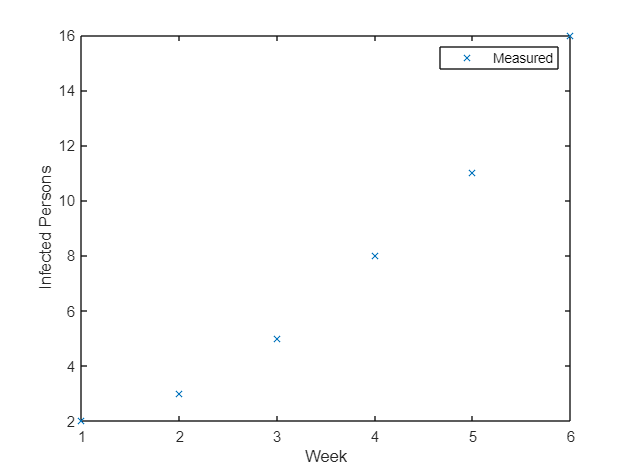

% Plot the data
figure()
plot(W_data, I_data, 'x', 'DisplayName', 'Measured')

xlabel("Week")
ylabel("Infected Persons")
legend()

### **Exercise 1 / 8**

Take a look at the values in I`_data`; what do you notice about the values?

*(Write your response here)*

Each week the number of persons infected each week increases by one. For example, from week 1 to 2 one person gets infected, then from 2 to 3 two more people get infected, then it increases to three people getting infected inbetween weeks and then to 4 and then 5.

**Compare your observations with someone else at your table. Did they notice anything different about the data?**

## Fitting Parameters

Since we have information about a scenario, we can try to adjust the parameters to match the available data: This process is called *fitting the model*. Let's compare the simulation results from the previous notebook. How well do arbitrary choices for $\beta, \gamma$ and the initial number of infected i_0 match the data?

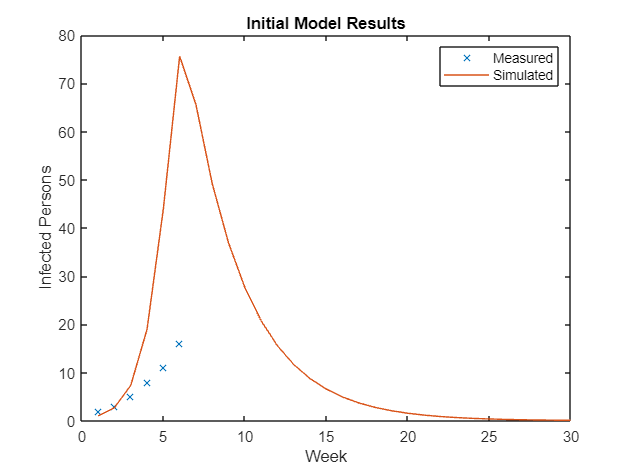

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_1 = 99;
i_1 = 1;
r_1 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 50;
gamma = 1 / 4;

% Run simulation
[S_sim, I_sim, R_sim, W_sim] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the data
figure()
plot(W_data, I_data, 'x', 'DisplayName', 'Measured'); hold on
plot(W_sim, I_sim, 'DisplayName', 'Simulated')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Initial Model Results")

### **Exercise 2 / 8**

Compare the measured and simulated curves. What is similar about them? What is different? What simulation settings might need tweaking?

*(Write your response here)*

Both curves are exponentially increasing, though the simulated model has a much sharper increase than what was measured. The simulated model also starts increasing linearly a little before week 5, something the measured model doesn't do.

Before we go randomly-changing model parameters, we should first get a handle on *model sensitivity*.

### Model sensitivity

All models are *sensitive—*to some degree or another—to their inputs; for instance, our SIR model results change with changes to the parameters $\beta, \gamma$ and starting conditions `s, i, r`. Before we go randomly-changing these values in an attempt to fit data, we should first build a *mental model* for how changing the inputs changes the simulation results: We should build intuition for the model sensitivity.

The following code slightly tweaks the value of $\gamma$, re-runs the simulation, and compares the baseline and tweaked model results.

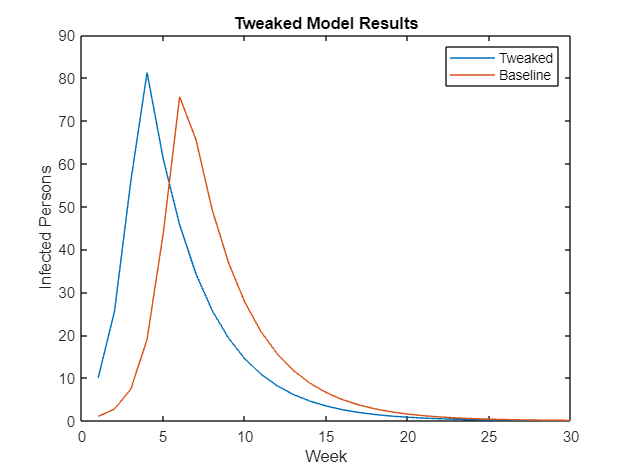

% Define parameters
beta = 1 / 50;  % Baseline: beta = 1 / 50
gamma = 1 / 4; % Baseline: gamma = 1 / 4
i_1 = 10;        % Baseline: i_0 = 1

% Define initial state
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_twk, I_twk, R_twk, W_twk] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the data
figure()
plot(W_twk, I_twk, 'DisplayName', 'Tweaked'); hold on
plot(W_sim, I_sim, 'DisplayName', 'Baseline')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Tweaked Model Results")

### **Exercise 3 / 8**

Systematically adjust the values of $\beta, \gamma$ and `i_1. `Record what each value *physically represents*, and document how changing their values tend to affect model results. Which of $\beta, \gamma$ and `i_1` tends to *most dramatically* change the results? Which tends to *least dramatically* change the results?

- $\beta$ represents rate of people being infected: Increasing $\beta$ tends to increase the max number of infected people

- $\gamma$ represents rate of people recovering: Increasing $\gamma$ tends to decrease the max number of infected people

- `i_1` represents The number of infected people: Increasing `i_1` tends to change the rate at which people get infected

### Sensitivity analysis via parameter sweep

Manually tweaking values is an *extremely crude* way to do a sensitivity analysis, but we've already learned a better way: *parameter sweeps*. Let's put parameter sweeps to use to help understand the compartmental SIR model's sensitivity to parameters.

### Exercise 4 / 8

Use the ending value of the Susceptible stock as your metric. Perform two parameter sweeps: One over the values in `Beta_all`, and another over the values in `Gamma_all`. Answer the questions below.

*Bonus:* You can use the `subplot()` command to put the two plots together. Read the documentation (type `help subplot`) to learn how!

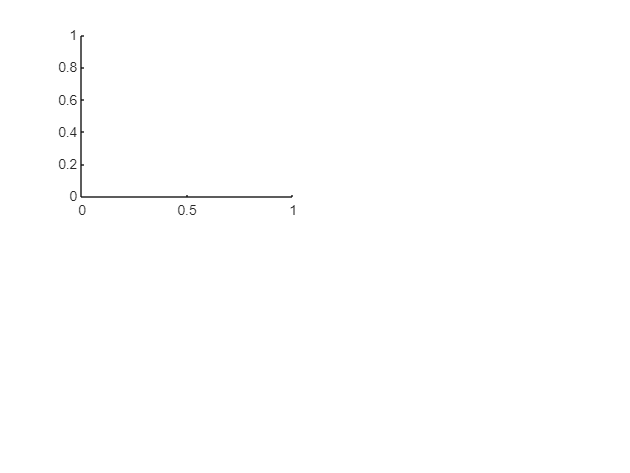

% NOTE: Do not edit these values
t_end = 40;
beta_middle = 1/50; % Set a "nominal" value for beta
gamma_middle = 1/4; % Set a "nominal" value for gamma
% Sweep above and below the nominal values
Beta_all = linspace(beta_middle / 10, beta_middle * 10, 100);
Gamma_all = linspace(gamma_middle / 10, gamma_middle * 10, 100);

% TODO: Do a parameter sweep over Beta_all, use gamma_middle for all cases
S_metric = zeros(size(Beta_all));

% Loop over all beta values
for i = 1 : length(Beta_all)
    % Simulate with the desired beta
    beta_temp = Beta_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, beta_temp, gamma_middle, t_end);
    % Compute and store the metric value
    S_metric(i) = max(I);
end

% Visualize the results
subplot(2,2,1)

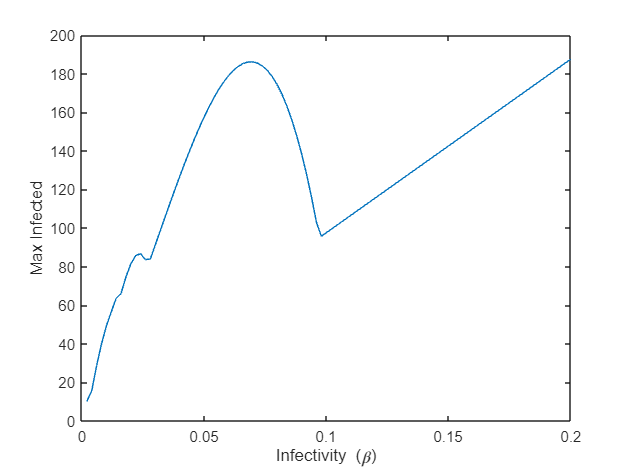

figure()
plot(Beta_all, S_metric)
xlabel('Infectivity (\beta)')
ylabel('Max Infected')

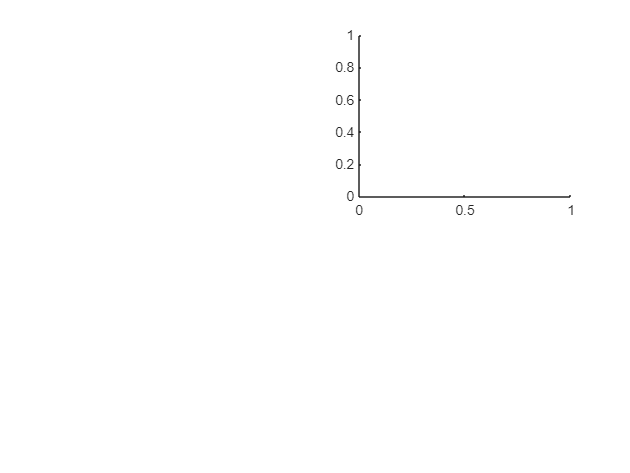

% TODO: Do a parameter sweep over Gamma_all, use beta_middle for all cases
t_end = 40;
beta_middle = 1/50; % Set a "nominal" value for beta
gamma_middle = 1/4; % Set a "nominal" value for gamma
% Sweep above and below the nominal values
Beta_all = linspace(beta_middle / 10, beta_middle * 10, 100);
Gamma_all = linspace(gamma_middle / 10, gamma_middle * 10, 100);

% TODO: Do a parameter sweep over Beta_all, use gamma_middle for all cases
S_metric = zeros(size(Gamma_all));

% Loop over all beta values
for i = 1 : length(Gamma_all)
    % Simulate with the desired beta
    Gamma_temp = Gamma_all(i);
    [S, I, R, W] = simulate_sir(s_1, i_1, r_1, Gamma_temp, beta_middle, t_end);
    % Compute and store the metric value
    S_metric(i) = max(I);
end

% Visualize the results
subplot(2,2,2)

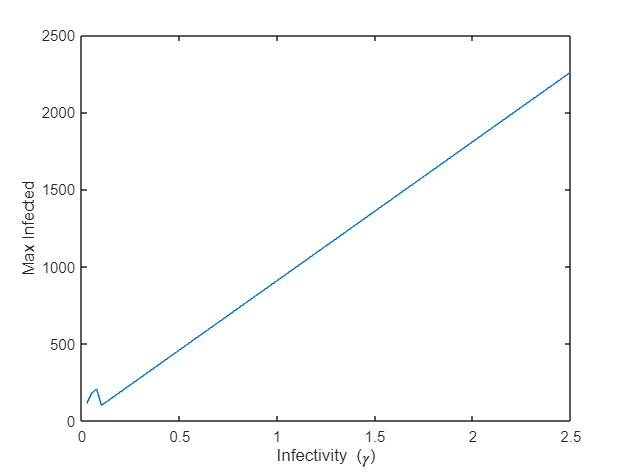

figure()
plot(Gamma_all, S_metric)
xlabel('Infectivity (\gamma)')
ylabel('Max Infected')

- What effect does the Infectivity ($\beta$) have on the ending S value?

- *(Write your response here) *It decreases the ending S value.

- What effect does the Recovery Rate ($\gamma$) have on the ending S value?

-  *(Write your response here) *It decreases the ending S value.

- Are there any "flat" regions in either curve? Where are they?

-  *(Write your response here) *The beta curve has flat regions in a small region between 0 and 0.05 and in a small region between 0.05 and 0.1.The gamma curve has a flat region in a small spot in the very beginning

- Which curve is steeper? (*Note:* "Steepness" is one way to measure model sensitivity)

- The beta curve is steeper.

-  *(Write your response here)*

**Compare your parameter sweeps and observations with someone else at your table. Did you get the same results?**

## Principled Model Fitting

Now that we have some physical understanding of our model inputs $\beta, \gamma$ and `i_1`, we can do some *principled* model fitting. First, we'll use our physical understanding of the inputs to try to set some of them directly. Then we'll use the data to try to set the remaining parameters.

**Direct Setting**: We know from the scenario how many people were infected at Week 1; it's in our dataset!

% Look at week zero
tab_data(tab_data.W == 1, :)

ans = 1×2 table
    W    I
    _    _

    1    2


Thus we can set `i_1 = 2` directly!

### Simulation 1: Single patient recovery

We also have data related to $\gamma$ in the form of the following data:

> From clinical study of infected individuals, we know it takes two weeks for a person to become $1/4$ as infectious as a freshly-infected individual.

These data are harder to use, though! We can't just set $\gamma = 1/4$ as this parameter does not directly relate to the infectiousness of a person after two weeks. However, we can use the model to *simulate* a scenario where we are studying a single infected patient!

### Exercise 5 / 8

Determine the initial conditions of the model that correspond to the clinical setting above.

% TODO: Determine the correct initial conditions
s_1 = 0; % Incorrect value! Determine the correct one
i_1 = 1; % Incorrect value! Determine the correct one
r_1 = 0; % Incorrect value! Determine the correct one


% NOTE: Do not edit this code; use this to check your work
assert(0 <= s_1, 's_0 must be non-negative')
assert(s_1 <= 100, 's_0 must not be larger than the total population')
assert(0 <= i_1, 'i_0 must be non-negative')
assert(i_1 <= 100, 'i_0 must not be larger than the total population')
assert(0 <= r_1, 'r_0 must be non-negative')
assert(r_1 <= 100, 'r_0 must not be larger than the total population')
assert(s_1 + i_1 + r_1 == 1, 'We are studying *only one* person at a time....')
assert(~(s_1 > 0), 'We are studying an *infected* person...')
assert(~(r_1 > 0), 'We are studying an *infected* person...')
disp('Assertions passed!')

Assertions passed!


Once you have determined how to simulate the clinical setting, we can use the model to convert the clinical data into a $\gamma$ value.

*Note:* We can do this because the scenario in question *does not depend on* $\beta$. Disease transmission is not relevant in this scenario, only recovery!

### Exercise 6 / 8

Modify the value of $\gamma$ to match the clinical data provided above. Explain below why your results match the clinical data given above.

*Hint:* Do not just randomly try values of $\gamma$! Use the results of the sensitivity analysis you performed above.

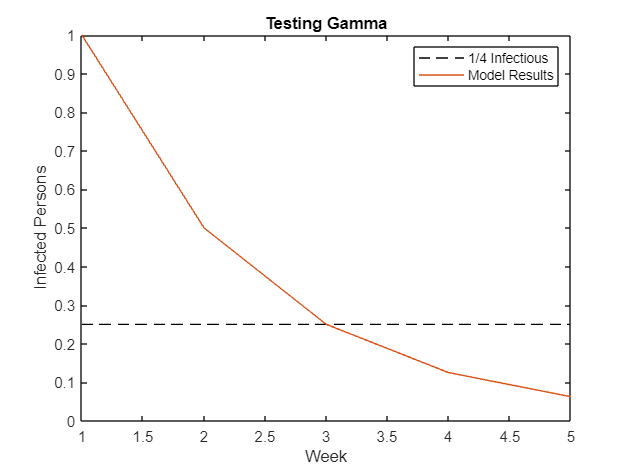

% TODO: Tweak gamma to match the clinical data as-provided
gamma = 1/2;

% NOTE: Do not edit this code. Run simulation
[~, I_gam, ~, W_gam] = simulate_sir(s_1, i_1, r_1, beta, gamma, 5);


% Plot the data
figure()
plot([1, W_gam(end)], [0.25, 0.25], 'k--', 'DisplayName', '1/4 Infectious'); hold on
plot(W_gam, I_gam, 'DisplayName', 'Model Results')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Testing Gamma")


% NOTE: Do not edit this code; use this to check your work
assert(abs(I_gam(3) - 1/4) < 1e-3, 'Incorrect value of gamma')
disp('Assertions passed')

Assertions passed


- Why does this simulation match the clinical results given above?

-  *(Write your response here) *Because with this value for gamma the infection rate is 1/4 after 2 weeks.

### Simulation 2: Spread across a susceptible population

The parameter $\beta$ is a bit trickier to set; we don't have any direct information on the infectiousness of the disease. However, since we've set all the other parameters in the model (`i_0` and `gamma`), we can use the measured data to fit the remaining parameter by manually tweaking $\beta$ to match. Let's see how the simulation compares with the measured data when we set a completely arbitrary value for $\beta$:

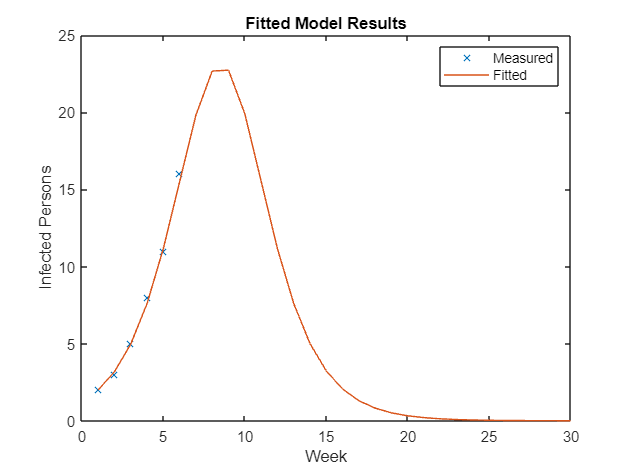

% TODO: Fit this parameter
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / week)

% NOTE: We fit these parameters directly in the steps above
gamma = 1 / 2; % Recovery rate
i_1 = 2;       % Initial count of infected persons

% Define initial state
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the data
figure()
plot(W_data, I_data, 'x', 'DisplayName', 'Measured'); hold on
plot(W_fit, I_fit, 'DisplayName', 'Fitted')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Fitted Model Results")

This is not a very good fit! You will improve the value of $\beta$ in the next exercise.

### **Exercise 7 / 8**

Manually fit the $\beta$ parameter by comparing the simulation results against data using the code above. Remember the exercise you did above: Keep in mind how changing $\beta$ tends to change the simulation results. What is the best-fit value for $\beta$ that you found?

-    1/90

**Compare your fitted parameter value with someone at your table. Did you get the same value?**

## Using the Model

Congratulations, you just fit your first model! Now that we have a fitted model, we can use it to *make predictions*. Remember that we only have data up through Week 6. We can use the model to make a prediction about future weeks.

### **Exercise 8 / 8**

Use your fitted model to plot the timeseries trends of the `S, I, R` stocks. Answer the questions below.

*Hint:* You can use earlier parts of this worksheet to help write the code for this exercise. 

beta = 1/90

beta = 0.0111

gamma - 1/2

ans = 0

s_1 = 98

s_1 = 98

i_1 = 2

i_1 = 2

r_1 = 0

r_1 = 0

[Sfinal, Ifinal, Rfinal, week] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30)

Sfinal =    98.0000   95.8222   92.4389   87.3319   79.9639   70.0443   57.9797   45.2142   33.8235   25.2822   19.6907   16.2899   14.2676   13.0614   12.3342   11.8913   11.6192   11.4511   11.3469   11.2822   11.2419   11.2167   11.2011   11.1913   11.1852   11.1814   11.1790   11.1776   11.1766   11.1761


Ifinal =     2.0000    3.1778    4.9722    7.5931   11.1646   15.5018   19.8155   22.6733   22.7273   19.9049   15.5440   11.1728    7.6087    5.0105    3.2324    2.0592    1.3017    0.8189    0.5136    0.3216    0.2011    0.1257    0.0785    0.0490    0.0306    0.0191    0.0119    0.0074    0.0046    0.0029


Rfinal =          0    1.0000    2.5889    5.0750    8.8716   14.4538   22.2048   32.1125   43.4492   54.8128   64.7653   72.5373   78.1237   81.9281   84.4333   86.0495   87.0791   87.7300   88.1394   88.3962   88.5570   88.6576   88.7204   88.7597   88.7842   88.7995   88.8090   88.8150   88.8187   88.8210


week =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


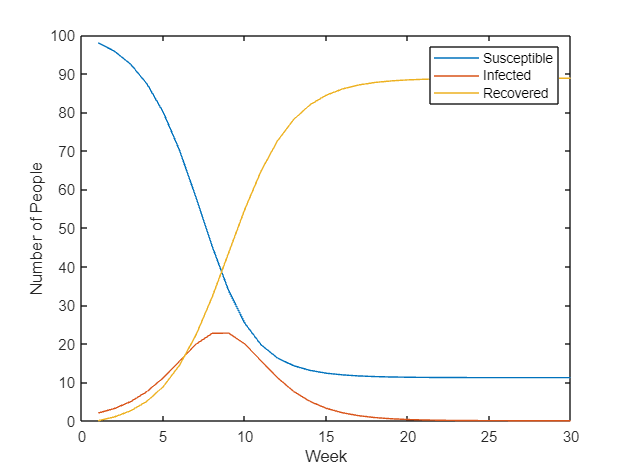

figure()
plot(week, Sfinal, 'DisplayName', 'Susceptible')
hold on
plot(week, Ifinal, 'DisplayName', 'Infected')
plot(week, Rfinal, 'DisplayName', 'Recovered')
legend()
xlabel("Week")
ylabel("Number of People")

*(Write your response here; you will need to add a code section to complete this exercise. You can do this with the "Code" button in the ribbon menu at the top of MATLAB:)*

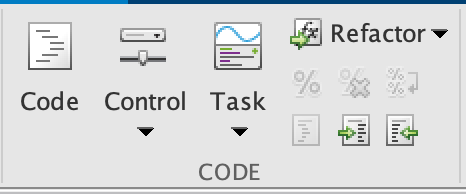

- When will this flu outbreak be over?

-  *(Write your response here) *Inbetween 15-20 weeks.

- How many of the 100 total persons will fall ill with the flu?

-  *(Write your response here) *Inbetween 80 and 100

- How much confidence do you have in your answers to these questions? Why or why not?

-  *(Write your response here) *I have like 90% confidence in these answers because the values for beta and gamma were very close to the measured data. Of course, there's always room for error and circumstances not taken into account with models, which is why I say 90%.

## End Notes

In this notebook we used manual techniques for fitting model parameters. Scientists will use more automated techniques such as [least squares](https://en.wikipedia.org/wiki/Least_squares) to fit models to data. You will learn about least squares in QEA!

## Looking Forward

In the next notebook we'll dig deeper into how we check a model through *validation, *and learn how things can go wrong when we're *missing some physics in our model.*